# Optimizing Gemm Step 1

This Live Script helps you visualize the performance of the implementation of matrix-matrix multiplication casted as Axpy operations in GemmIPJ_Axpy.c.

To gather the performance data, execute 

clear

system('make test_GemmIPJ_Axpy')

gcc -O2 -Wall -I/u/dnp/blis/include/blis -m64 -msse3 -std=c99 -D_POSIX_C_SOURCE=200112L   -c -o driver_GemmIPJ_Axpy.o driver_GemmIPJ_Axpy.c
driver_GemmIPJ_Axpy.c: In function ‘main’:
driver_GemmIPJ_Axpy.c:51:3: warning: ignoring return value of ‘scanf’, declared with attribute warn_unused_result [-Wunused-result]
   scanf( "%d", &nrepeats );
   ^
driver_GemmIPJ_Axpy.c:57:3: warning: ignoring return value of ‘scanf’, declared with attribute warn_unused_result [-Wunused-result]
   scanf( "%d%d%d", &first, &last, &inc );
   ^
gcc -O2 -Wall -I/u/dnp/blis/include/blis -m64 -msse3 -std=c99 -D_POSIX_C_SOURCE=200112L   -c -o GemmIPJ_Axpy.o GemmIPJ_Axpy.c
gcc driver_GemmIPJ_Axpy.o GemmIPJ_Axpy.o Axpy.o FLA_Clock.o MaxAbsDiff.o RandomMatrix.o /u/dnp/blis/lib/libblis.a -o driver_GemmIPJ_Axpy.x -lpthread -m64 -lm  
echo "3 32 500 32" | ./driver_GemmIPJ_Axpy.x > output_data_GemmIPJ_Axpy.m


ans = 0

When completed, this creates output file 'output_data_GemmIPJ_Axpy.m' with timing data.  This Life Script then creates graphs from that timing data.

## Step 1a: Load timing data

output_data_GemmIPJ_Axpy

## Step 1b: Make sure you are getting the right answer

In output_data_GemmIPJ_Axpy.m, for each execution of GemmIJP_Axpy, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of $ 10^{-11} $ or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_GemmIPJ_Axpy( :, 3 ) ) )

MaxAbsDiff = 3.4106e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Step 1c: Plot the timing data.

The first graph shows the execution time of the different implementations as a function of the matrix size $n$.

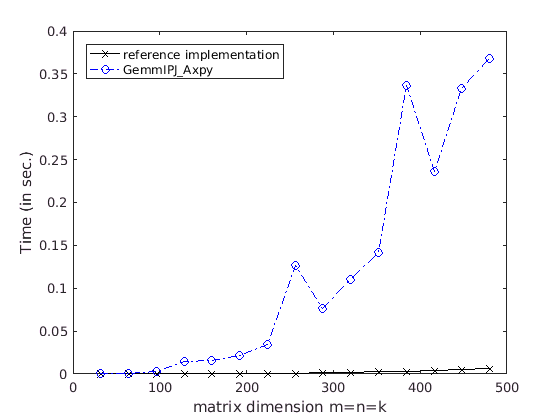

close all

% Plot the reference implementation performance
plot( data_ref( :,1 ), data_ref( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

plot( data_GemmIPJ_Axpy( :,1 ), data_GemmIPJ_Axpy( :, 2 ), 'b-.o' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Time (in sec.)' );
legend( 'reference implementation', ...
        'GemmIPJ\_Axpy', ...
        'Location', 'NorthWest' );

% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

Notice that the reference implementationis considerably faster than the implmentation of "triple loop" IJP using the Axpy subroutine.  We illustrate that by plotting the speedup of the highly optimized reference implementation relative to GemmIPJ_Axpy.

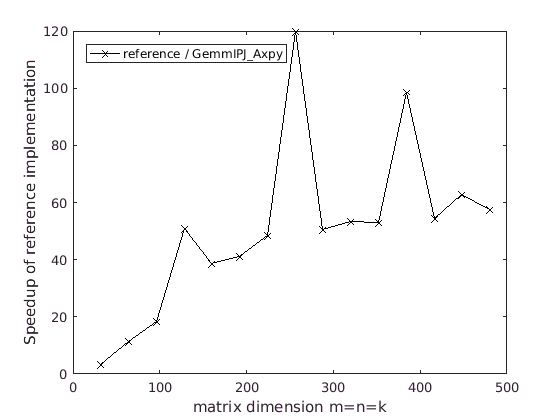

plot( data_ref( :,1 ), data_GemmIPJ_Axpy( :, 2 ) ./ data_ref( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Speedup of reference implementation' );
legend( 'reference / GemmIPJ\_Axpy', ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Step 3: Plot performance.

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.

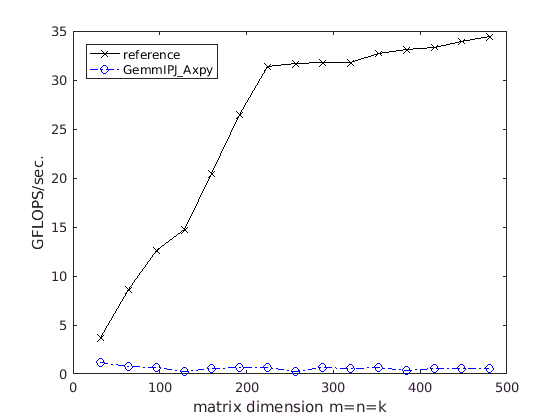

ns = data_ref( :, 1 );                                   % Extract a vector of matrix size.
gflops = 2.0 * ns.^3 ./ data_ref( :, 2 ) * 1.0e-9;       % Compute a vector of corresponding 
                                                         % GFLOPS/sec from the timing data.
plot( ns, gflops, 'k-x' );                               % Plot the performance data

hold on

ns = data_GemmIPJ_Axpy( :, 1 );
gflops = 2.0 * ns.^3 ./ data_GemmIPJ_Axpy( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'b-.o' ); 

xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS/sec.' );
legend( 'reference', ...
        'GemmIPJ\_Axpy', ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Conclusion